# **Projetar as funções de transferência dos filtros ativos que seguem com aproximação Butterworth:**

Deve ser apresentado  todo o equacionamento para se obter as funções de transferência a partir das funções normalizadas (polinômios de Butterworth). A partir da  função de transferência, apresentar a resposta em frequência do filtro  (magnitude e fase).  Apresentar ao menos simulações de sinais senoidais  (sobrepor sinal de entrada e saída) na banda passante, na frequência de  corte e na banda de rejeição dos filtros. Comparar os resultados obtidos na simulação com os previstos pela resposta em frequência.

clc;
clear;
K = 1;
s = tf("s");
interval = {0, 10^10};
rad_s = 2 * pi; % 1 Hz = 2 * pi rad/s

function simulate_filter_response(H, f, T)
    dt = 1e-7; 
    t = 0:dt:T; 
    u = sin(2 * pi*f*t); 
    
    [y, t_out] = lsim(H, u, t);
   
    figure;
    plot(t_out, u, 'b', t_out, y, 'r');
    xlabel('Tempo (s)');
    ylabel('Amplitude');
    legend('Entrada', 'Saída');
    title(['Resposta do Filtro (f = ' num2str(f) ' Hz, Tempo Simulado = ' num2str(T) ' s)']);
    grid on;
end

**1) Passa-baixas de primeira ordem com frequência de corte de 250 Hz.**

disp("Passa baixa 250Hz - 1ª Ordem");

Passa baixa 250Hz - 1ª Ordem


Hz = 250;
a = s / (Hz * rad_s);

% polinomio normalizado de primeira ordem
butterworth_p_1 = a + 1;
H = 1 / butterworth_p_1


H =
 
    1571
  --------
  s + 1571
 
Continuous-time transfer function.
Model Properties


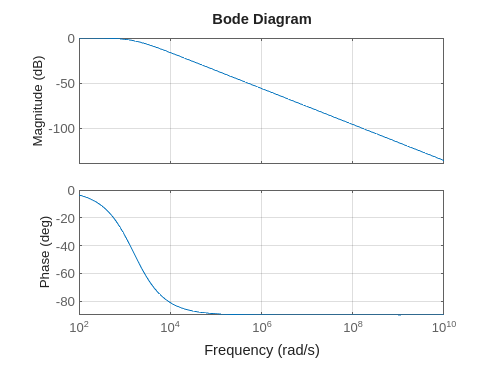


bode(H, interval)
grid on;

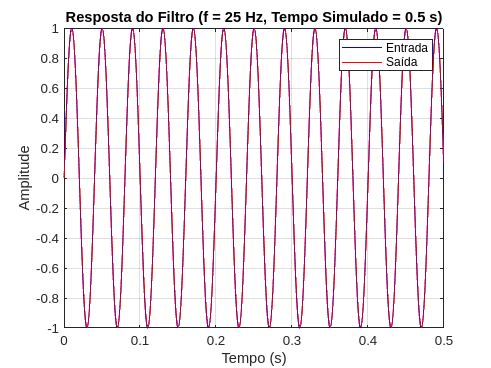


simulate_filter_response(H, Hz/10, 0.5);

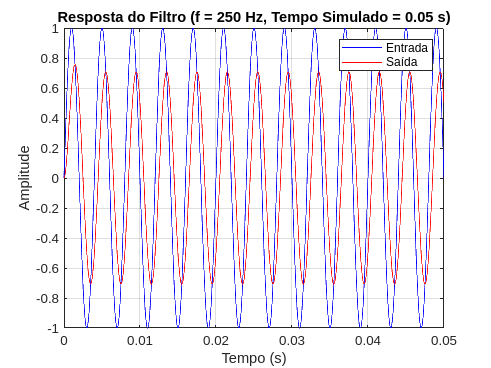

simulate_filter_response(H, Hz, 0.05);

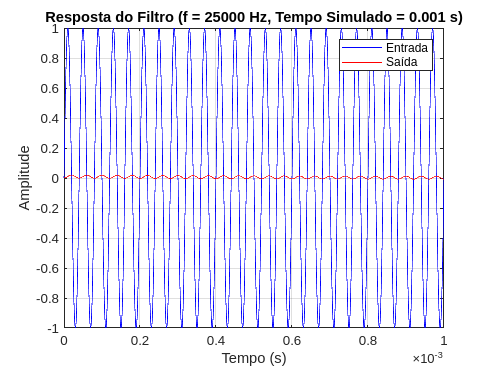

simulate_filter_response(H, Hz*100, 0.001);

**2) Passa-altas de primeira ordem com frequência de corte de 250 Hz. **

disp("Passa alta 250Hz - 1ª Ordem");

Passa alta 250Hz - 1ª Ordem


Hz = 250;
a = s / (Hz * rad_s);

% polinomio normalizado de primeira ordem
butterworth_p_1 = a + 1;
H = (a^1) / butterworth_p_1


H =
 
       1571 s
  -----------------
  1571 s + 2.467e06
 
Continuous-time transfer function.
Model Properties


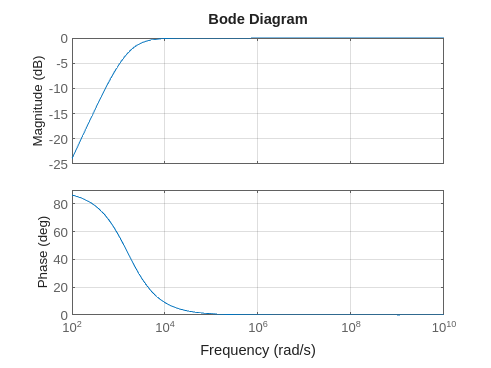


bode(H, interval)
grid on;

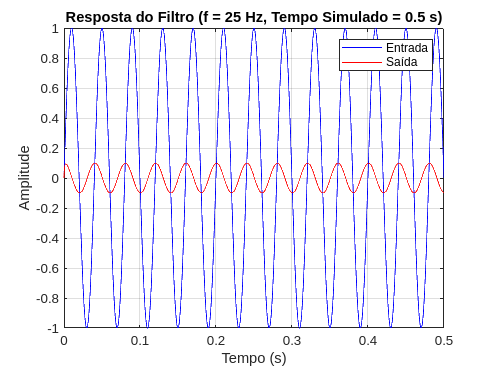


simulate_filter_response(H, Hz/10, 0.5);

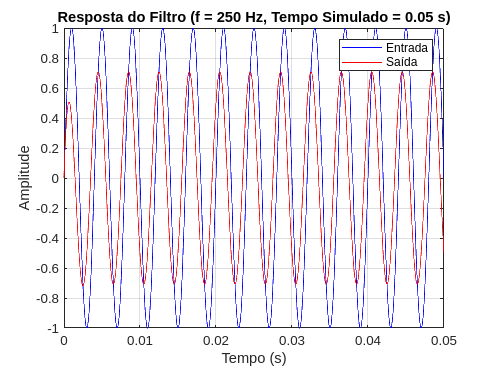

simulate_filter_response(H, Hz, 0.05);

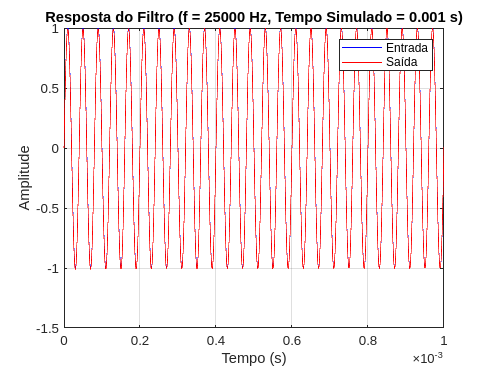

simulate_filter_response(H, Hz*100, 0.001);

**3) Passa-baixas de segunda ordem com frequência de corte de 250 Hz.**

disp("Passa baixa 250Hz - 2ª Ordem");

Passa baixa 250Hz - 2ª Ordem


a = s / (Hz * rad_s);

% polinomio normalizado de segunda ordem
butterworth_p_2 = a^2 + a*1.4142 + 1;
H = 1 / butterworth_p_2


H =
 
              3.876e09
  --------------------------------
  1571 s^2 + 3.489e06 s + 3.876e09
 
Continuous-time transfer function.
Model Properties


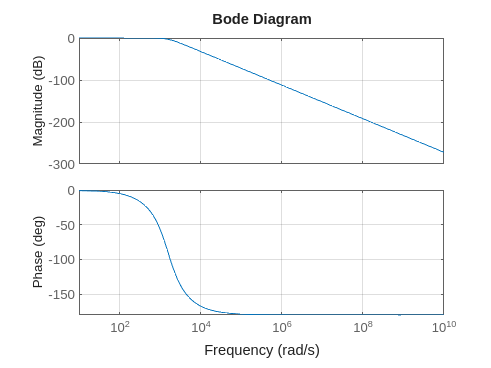


bode(H, interval)
grid on;

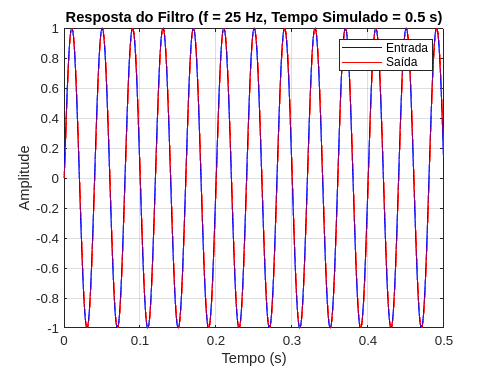


simulate_filter_response(H, Hz/10, 0.5);

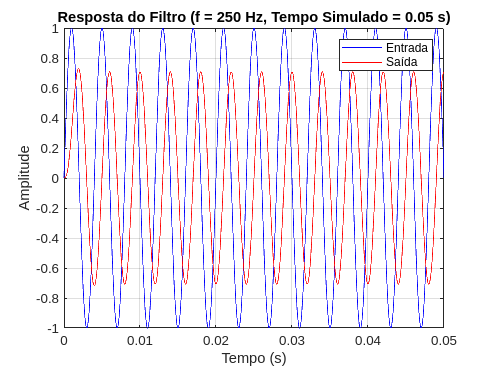

simulate_filter_response(H, Hz, 0.05);

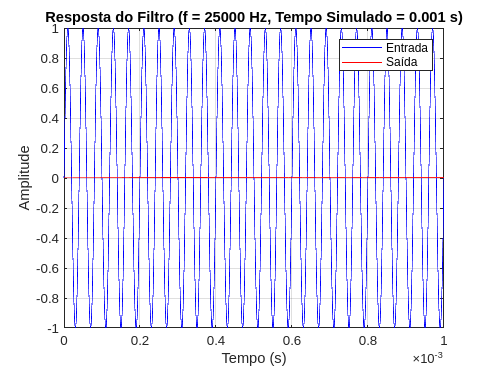

simulate_filter_response(H, Hz*100, 0.001);

**4) Passa-altas de segunda ordem com frequência de corte de 250 Hz. **

disp("Passa alta 250Hz - 2ª Ordem");

Passa alta 250Hz - 2ª Ordem


Hz = 250;
a = s / (Hz * rad_s);

% polinomio normalizado de segunda ordem
butterworth_p_2 = a^2 + a*1.4142 + 1;
H = (a^2) / butterworth_p_2


H =
 
             3.876e09 s^2
  -----------------------------------
  3.876e09 s^2 + 8.61e12 s + 9.563e15
 
Continuous-time transfer function.
Model Properties


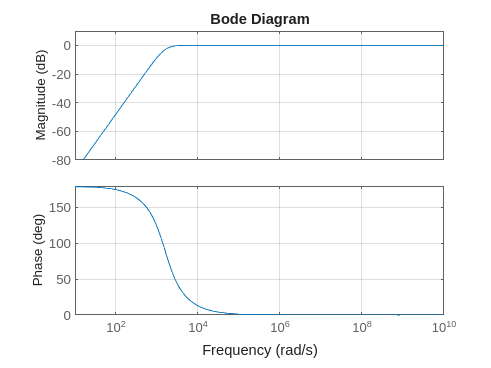


bode(H, interval)
grid on;

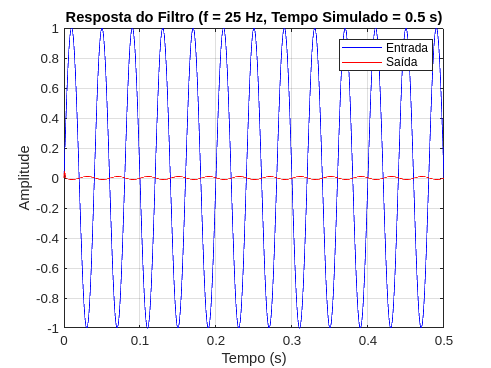


simulate_filter_response(H, Hz/10, 0.5);

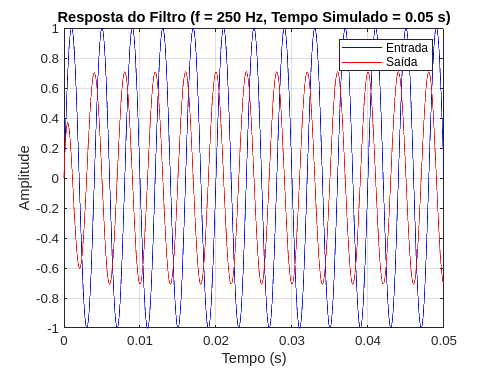

simulate_filter_response(H, Hz, 0.05);

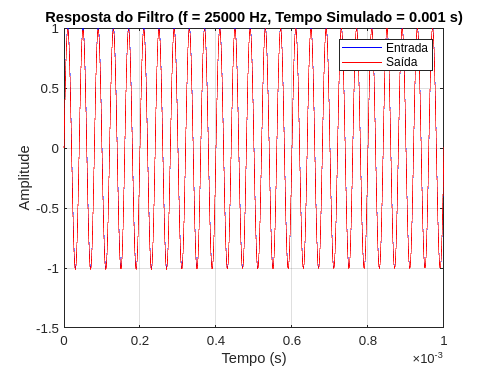

simulate_filter_response(H, Hz*100, 0.001);

**5) Passa-banda de segunda ordem com frequência central de 250 Hz e banda passante de 1000 Hz.**

disp("Passa banda 250Hz - 2ª Ordem");

Passa banda 250Hz - 2ª Ordem


Hz_center = 250;
Bw_Hz = 1000;

omega0 = Hz_center * rad_s;
B = Bw_Hz * rad_s;
% transformação de frequência passa-banda (passa baixa p/ passa banda)
a = (s^2 + omega0^2) / (B * s); 

% polinomio normalizado de primeira ordem
butterworth_p_1 = a + 1


butterworth_p_1 =
 
  s^2 + 6283 s + 2.467e06
  -----------------------
          6283 s
 
Continuous-time transfer function.
Model Properties


% quando substituir = B*s / (s^2 + B*s + omega0^2) --> segunda ordem
H = 1 / butterworth_p_1  


H =
 
          6283 s
  -----------------------
  s^2 + 6283 s + 2.467e06
 
Continuous-time transfer function.
Model Properties


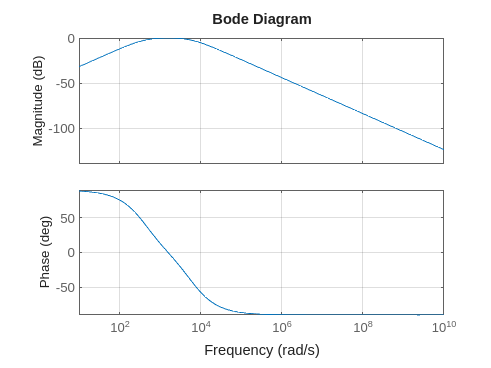


bode(H, interval);
grid on;

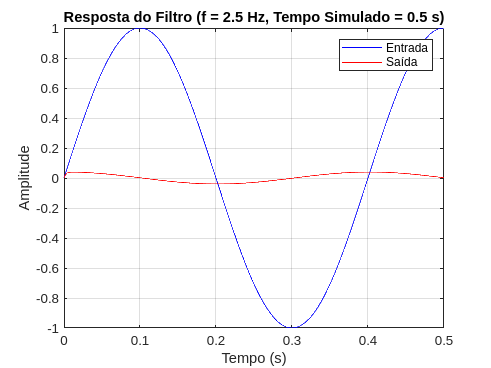


simulate_filter_response(H, Hz_center/100, 0.5);

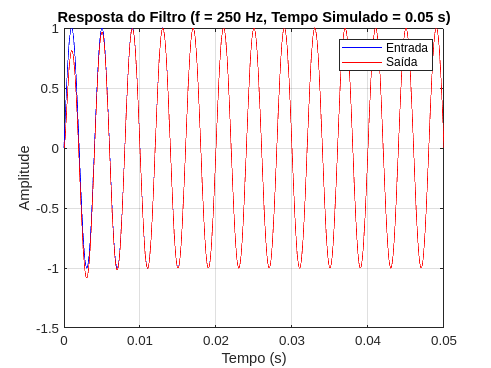

simulate_filter_response(H, Hz_center, 0.05);

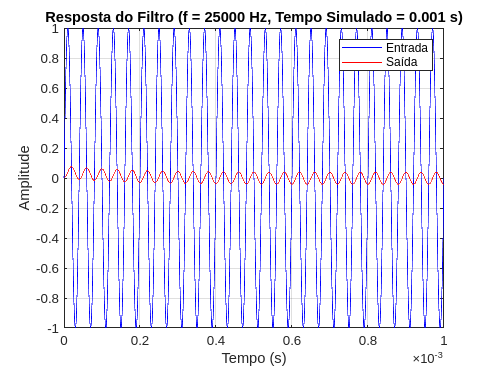

simulate_filter_response(H, Hz_center*100, 0.001);

**6) Rejeita-banda de segunda ordem com frequência central de 250 Hz e banda passante de 1000 Hz.**

disp("Rejeita Banda 250Hz ~ 1000Hz - 2ª Ordem");

Rejeita Banda 250Hz ~ 1000Hz - 2ª Ordem


Hz_center = 250;
Bw_Hz = 1000;

omega0 = Hz_center * rad_s;
B = Bw_Hz * rad_s

B = 6.2832e+03


% TESTE 1
H_TEST = H^(-1)


H_TEST =
 
  s^2 + 6283 s + 2.467e06
  -----------------------
          6283 s
 
Continuous-time transfer function.
Model Properties


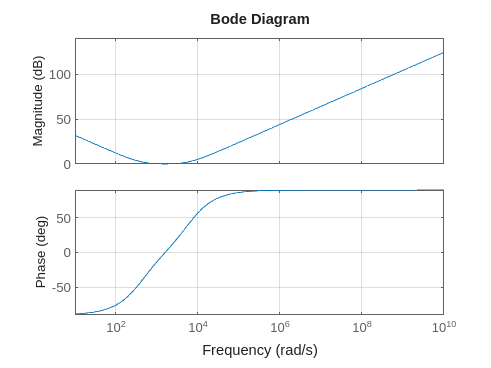

bode(H_TEST, interval);
grid on;

%simulate_filter_response(H_TEST, Hz_center/10, 0.5);
%simulate_filter_response(H_TEST, Hz_center, 0.05);
%simulate_filter_response(H_TEST, Hz_center*10, 0.001);
% FIM DO MEU TESTE --> DEU ERRADO KKKKKKK
% O gráfico inverte conforme eu pensei que fosse mas como
% a função de transferencia não é causal o lsim não consegue 
% simular.
% Como ver a resposta de um sistema não causal?

% TESTE 2: Resultando num filtro notch
a = (B * s) / (s^2 + omega0^2); 
butterworth_p_1 = a + 1


butterworth_p_1 =
 
  s^2 + 6283 s + 2.467e06
  -----------------------
      s^2 + 2.467e06
 
Continuous-time transfer function.
Model Properties


H = 1 / butterworth_p_1  


H =
 
      s^2 + 2.467e06
  -----------------------
  s^2 + 6283 s + 2.467e06
 
Continuous-time transfer function.
Model Properties


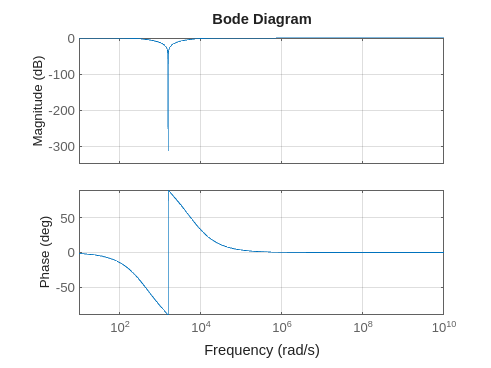

bode(H, interval);
grid on;

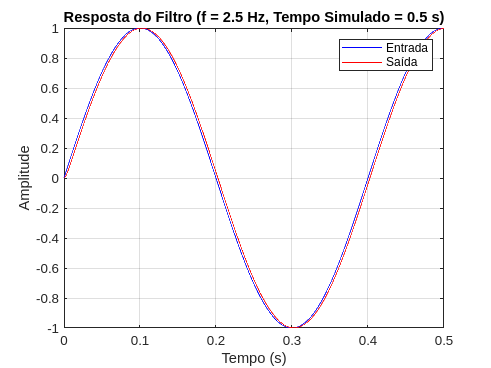

simulate_filter_response(H, Hz_center/100, 0.5);

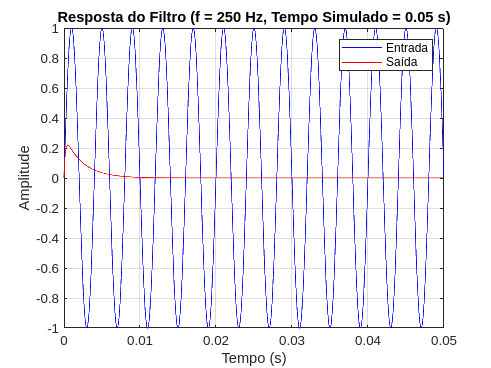

simulate_filter_response(H, Hz_center, 0.05);

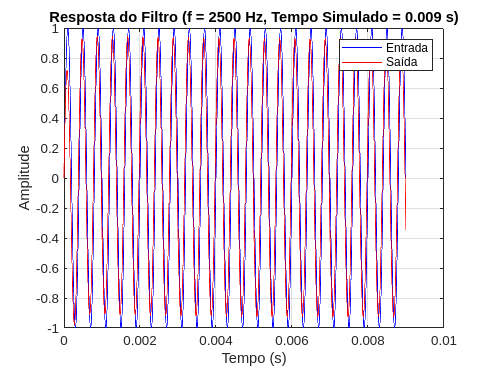

simulate_filter_response(H, Hz_center*10, 0.009);


% TESTE 3: Resultando num filtro ???
a = (B) / (s^2 + omega0^2); 
butterworth_p_1 = a + 1


butterworth_p_1 =
 
  s^2 + 2.474e06
  --------------
  s^2 + 2.467e06
 
Continuous-time transfer function.
Model Properties


H = 1 / butterworth_p_1  


H =
 
  s^2 + 2.467e06
  --------------
  s^2 + 2.474e06
 
Continuous-time transfer function.
Model Properties


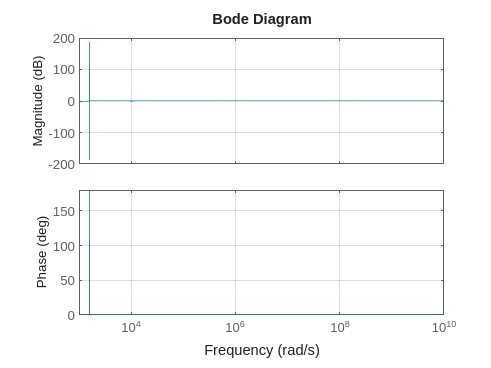

bode(H, interval);
grid on;

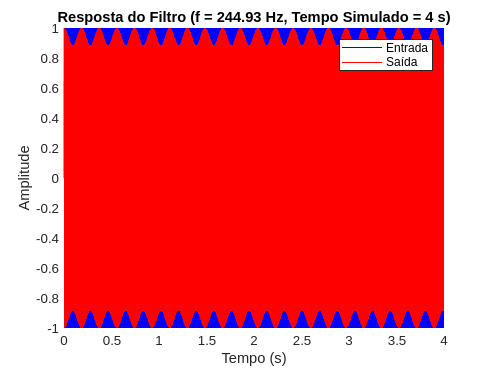

simulate_filter_response(H, 244.93, 4);

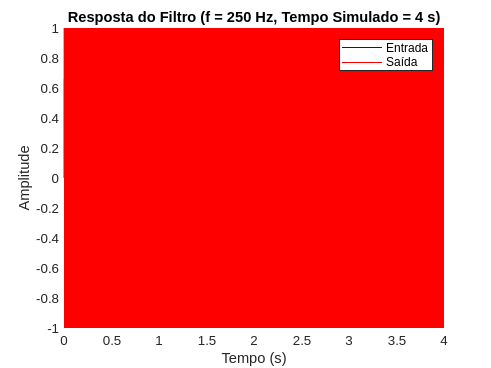

simulate_filter_response(H, Hz_center, 4);

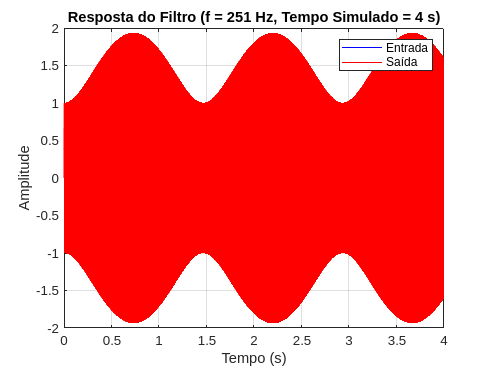

simulate_filter_response(H, 251, 4);